# F3_Run_LactinV_inSilico_Trial.m

**Goal**: Replicate Lactin-V clinical trial and compare predicted BV recurrences to clinically observed frequencies

**Study:** Cohen et al. (2020) - Randomized Trial of Lactin-V to Prevent Recurrence of Bacterial Vaginosis

**Requirements:**

MATLAB Toolboxes: Parallel Computing, Bioinformatics, Symbolic Math

Custom Scripts: Add the `probiotic_code/` folder to your path

Model inputs as defined in `define_Common_Simulation_Inputs `(*Defines virtual patient population, simulation inputs)*

*Functions:*

## 1. Load Model Defaults and Define Probiotic Strains

The Lactin-V study provided limited historical data on patient CSTs that could indicate what an appropriate population could be.

For this analysis, we will assess both a population based on the HMP cohort.

clear; clc;
ws_name = 'input_files/SSConfig-Analysis-HMP-Virtual-Population.mat';
simulationType = "comboLV";
[POPinfo,PROBinfo,ABXinfo,~] = define_Common_Simulation_Inputs(ws_name,simulationType);
output_fdr = 'result_workspaces/';

`POPinfo`: struct that defines virtual patient population

- `virtualPatientParameter`s: # patients x 20 parameter matrix generated by LHS

- `virtualPatientComposition`: 1 x # patients cell of analytically predicted steady-state absolute abundances of nAB, Li, oLB (predicted without considering probiotic in community)

- `initialComposition`: scaling factor to "displace" from the predicted composition (POPinfo.virtualPatientComposition). For example, 0.01 is a 1% decrease in abundance and 0.05 is a 0.5% increase from the predicted abundance

- `Indexes`: indexes relative to original LHS array

- `odeOptions`: "options" input for ode solvers

- `odeSolver:` ODE solver function handle (e.g., @ode45, @ode15s)

`PROBinfo`: struct that defines probiotic parameters

- `dose`: absolute abundance of probiotic when dosed into the base community (selected from relative abundance data observed in Dausset et al. 2018)

- `numberDoses`: total number of doses given

- `doseFrequency`: time separation (days) between each dose

- `strainCharacteristics`: parameter values for the tested strain

- `strainCharIndexes`: probiotic characteristics parameter indexes relative to full parameter set

`ABXinfo`: struct that defines the antibiotic parameters

- AddABX: true if ABX is used, false if ABX is not used

- dose: magnitude of the ABX effect (based on Mayer et al. 2015)

- duration: length of ABX regimen (5-7days)

**Define Strains to Evaluate**

- Null Probiotic (mean/moderate values all around)

- Traditional Probiotic (null + nAB ->P set to -0.012)

- Moderate Probiotic (weak competition alll around, strong nAB->P to weak nAB->P; 2:1 ratio)

- Bad Probiotic (weak competition alll around, weak nAB->P to strong nAB->P; 2:1 ratio)

nullP = [0.5 0 0 0 0 0 0 -0.022]; % Null Probiotic
modP = [0.5 -0.006  -0.04 -0.04 -0.012 -0.04 -0.04 -0.022]; % Moderate Probiotic
badP = [0.5 -0.012  -0.04 -0.04 -0.006 -0.04 -0.04 -0.022]; % Bad Probiotic
tradP = [0.5 0 0 0 -0.012 0 0 -0.022]; % Traditional Probiotic

strainList = {nullP,tradP,modP,badP};
run_nms = {'Null','Traditional','Moderate','Bad'};

## 2. Set-up Clinical Regimens

Defining the Regimens: Requires input into structures for ABXinfo, PROBinfo, and POPinfo.

Within the define_Common_Simulation_Inputs.m, the Lactin-V Regimen is defined.

Treatment Arm (Placebo follows same dosing, but no probiotic within applicator):

- Week 0: 5 days intravaginal MTZ

- Week 1: Four consecutive days intravaginal probiotic

- Week 2-11: Twice weekly intravaginal probiotic

**Lactin-V Treatment Arm:**

An alternative ABX dose is -3.82. for a more moderate ABX effect, set to -2.64 d^-1.

ABXinfo.dose = -2.64; % moderate ABX effect
LactinV = {ABXinfo,PROBinfo,POPinfo};

**Lactin-V Placebo Arm:**

The placebo in the study was application of non-active agreements (no probiotic strain) of the Lactin-V formulation. To simullate the placebo, set the probiotic dose to zero and leave the `doseFrequency` and `numberDoses` equivalent to the Lactin-V Treatment arm.

PROBinfo.dose = 0; % relative unit

Placebo = {ABXinfo,PROBinfo,POPinfo};

Compile information into a cell array.

% ~~~~~~~~~~~~~~~~~ COMPILE DESIGNS INTO CELL ARRAY ~~~~~~~~~~~~~~~~~
TestDesigns = {LactinV, Placebo};

## 3. Run the Treatment and Placebo Arms

This code runs the in silico Lactin-V trial for 4 possible probiotic strain characteristics.

- Null Probiotic (mean/moderate values all around)

- Traditional Probiotic (null + nAB ->P set to -0.012)

- Moderate Probiotic (weak competition alll around, strong nAB->P to weak nAB->P; 2:1 ratio)

- Bad Probiotic (weak competition alll around, weak nAB->P to strong nAB->P; 2:1 ratio)

t = tic;
testDesignNames = {'Lactin-V','Placebo'};
numPatients = size(POPinfo.virtualPatientParameters,1);
for k = 1:length(strainList) % strain iteration
    all_select_outcomes = NaN(length(TestDesigns),numPatients,8+length(PROBinfo.customEvalPoints),5);
    all_warnall = NaN(length(TestDesigns),numPatients);
    probiotic_params = strainList{k};
    
    run_name = run_nms{k};
    for i = 1:length(TestDesigns) % Regigmen iteration
        tmp = TestDesigns{i};
        ABXinfo = tmp{1};
        PROBinfo = tmp{2};
        POPinfo = tmp{3};

        PROBinfo.strainCharacteristics = probiotic_params;
        [select_outcomes, ~, warnall, ...
            ~] = simulate_Clinical_Regimens_LV(ABXinfo,PROBinfo,POPinfo);
        all_select_outcomes(i,:,:,:) = select_outcomes;
        all_warnall(i,:) = warnall == "";
    end
    if isfolder(output_fdr)
        save(strcat(output_fdr,'F3_',run_name,'_LactinVPlacebo.mat'),'all_warnall','all_select_outcomes',...
            'testDesignNames','TestDesigns','probiotic_params')
    else
        mkdir(output_fdr)
        save(strcat(output_fdr,run_name,'-LactinVPlacebo.mat'),'all_warnall','all_select_outcomes',...
            'testDesignNames','TestDesigns','probiotic_params')
    end
end

Starting parallel pool (parpool) using the 'Processes' profile ...



tend = toc(t);
disp(strcat(num2str(tend/60), " minutes"))

## 4. Visualize the Results

HMP Population: ABX -2.64 d^{-1}


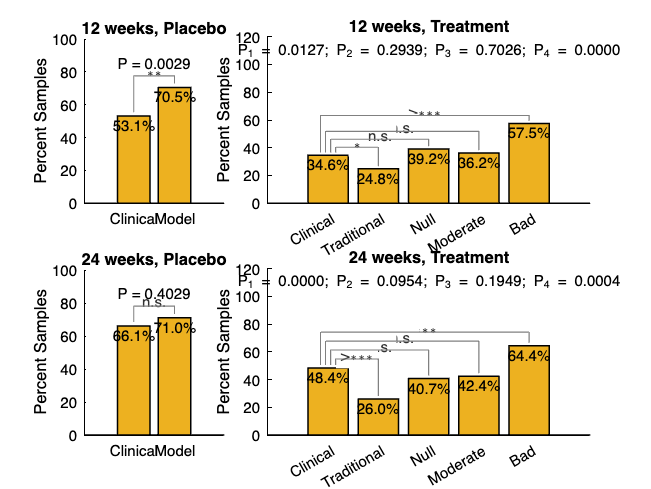

HMP Population: ABX -3.82 d^{-1}


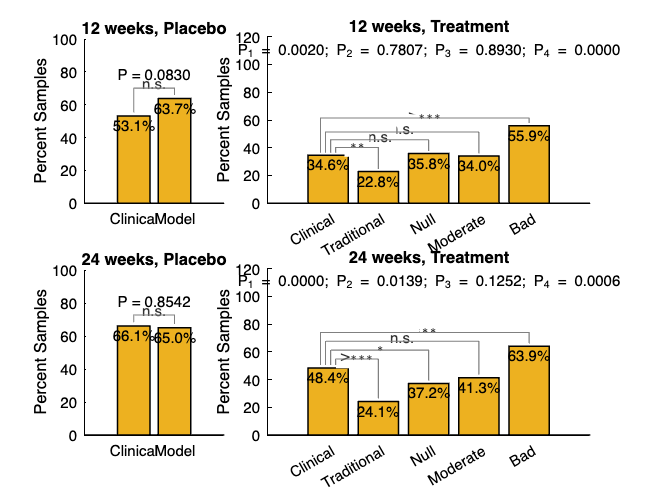


output_fdr = 'result_workspaces/';
sub_fdrs = {'LV_Trial_A264/','LV_Trial_A382/'};

ws_list = strcat('F3_',{'Traditional_LactinVPlacebo.mat',...
    'Null_LactinVPlacebo.mat',...
    'Moderate_LactinVPlacebo.mat',...
    'Bad_LactinVPlacebo.mat'});

sim_names = {'HMP Population: ABX -2.64 d^{-1}',...
    'HMP Population: ABX -3.82 d^{-1}'};

for i = 1:length(sub_fdrs)
    disp(sim_names{i})
    output_loc = strcat(output_fdr,'F3/',sub_fdrs{i});
    f(i) = figure;
    plot_LactinVSimulationvsObserved(output_loc,ws_list)
end